% Two sequential steps fit example
nbins=9; % number of bins in histograms
nboot=200; % number of bootstrap samples
global parm_names; % may not be necessary
dataset='kin28_comb_sub170_26sept_7feb';
run = '1';
load(dataset);
x = kin28_sub170_combined;
length(x)

ans = 146

x = x(x >3.0 & x < 500);
length(x)

ans = 135

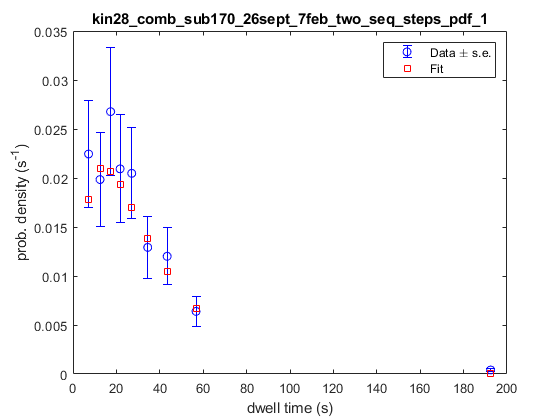

fit_parameters = 2×5 table
           Value      Lower_90pct_CI    Upper_90pct_CI    Lower_bound    Upper_bound
          ________    ______________    ______________    ___________    ___________

    k1     0.12783       0.077753           0.19418            0             10     
    k2    0.034162        0.02827          0.048273            0             10     


func=@two_seq_steps_pdf;
lbounds = [0, 0]; % constrain lower bounds of parameters
ubounds = [10, 10]; % constrain upper bounds of parameters
init_parm = [0.1, 0.01]; % initial param guesses
x_label = 'dwell time (s)';
y_label = 'prob. density (s^{-1})';
fitscript;